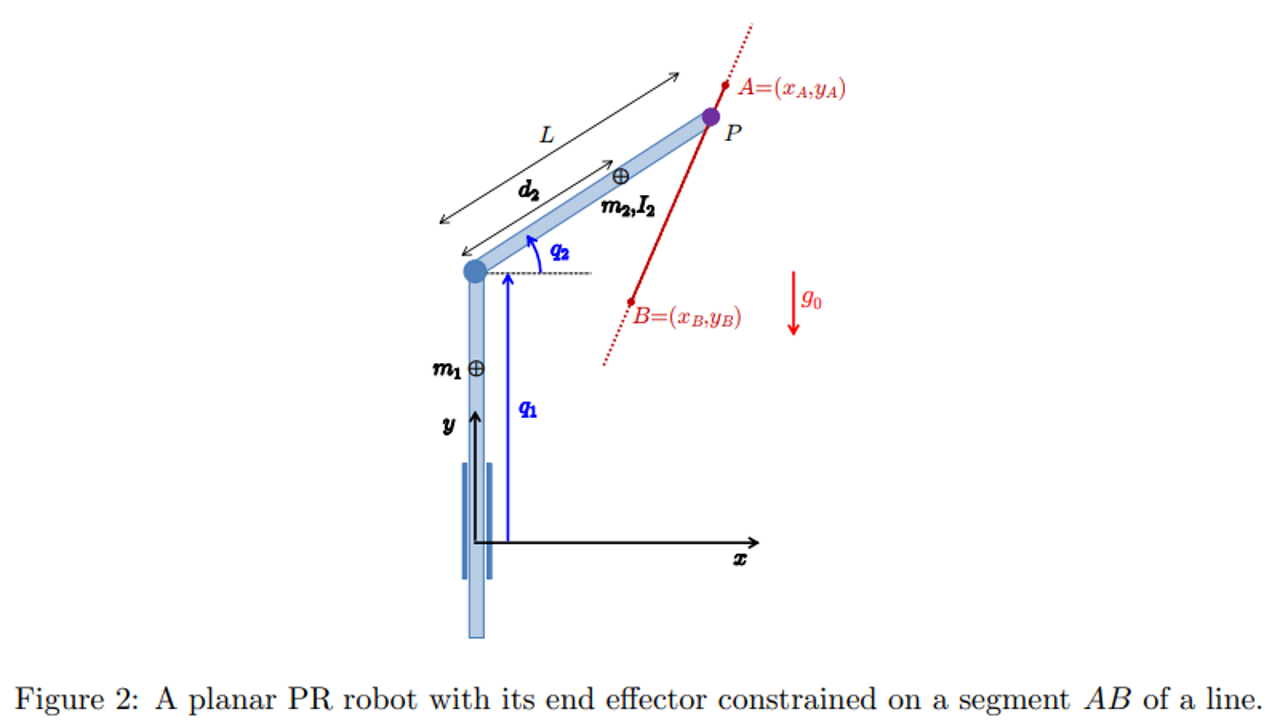

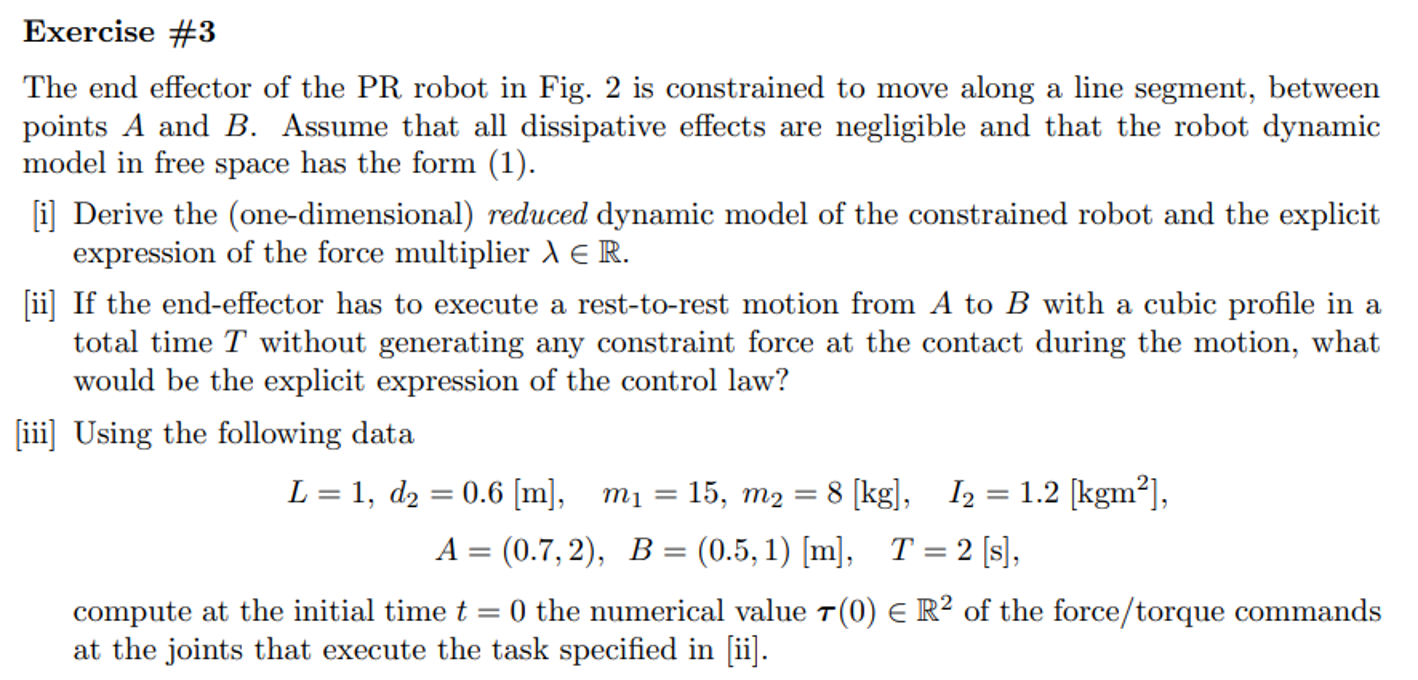

syms q1 q2 q3 q_dot_1 q_dot_2 q_dot_3 real
syms d_1 d_2 l_1 m_1 m_2 m_3 I_1 I_2 l_2 g0 positive
syms a1 a2 a3 L x_A x_B y_A y_B positive

% Dynamic model

T1 = 0.5*m_1*q_dot_1^2;

% joint 2 
x2 = d_2*cos(q2);
y2 = q1 + d_2*sin(q2);

vx2 = diff(x2,q1)*q_dot_1 + diff(x2,q2)*q_dot_2;
vy2 = diff(y2,q1)*q_dot_1 + diff(y2,q2)*q_dot_2;

T2_tr = 0.5*m_2*[vx2 vy2]*[vx2; vy2;];
T2_rot = 0.5*I_2*[0 0 q_dot_2]*[0; 0; q_dot_2;];
T2 = T2_tr + T2_rot

$$T2 = \frac{m_{2}\,{\left({\dot{q}}_{1}+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{{d_{2}}^{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}$$


% Total Energy
T = T1+T2

$$T = \frac{m_{2}\,{\left({\dot{q}}_{1}+d_{2}\,{\dot{q}}_{2}\,\cos\left(q_{2}\right)\right)}^{2}}{2}+\frac{I_{2}\,{{\dot{q}}_{2}}^{2}}{2}+\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}+\frac{{d_{2}}^{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}$$


% Inertia Matrix
M11 = diff(diff(T, q_dot_1), q_dot_1);
M12 = diff(diff(T, q_dot_1), q_dot_2);

M21 = diff(diff(T, q_dot_2), q_dot_1);
M22 = diff(diff(T, q_dot_2), q_dot_2);

M = [M11, M12;
     M21, M22;];
M = simplify(M)

$$M = \left(\begin{array}{cc} m_{1}+m_{2} & d_{2}\,m_{2}\,\cos\left(q_{2}\right)\\ d_{2}\,m_{2}\,\cos\left(q_{2}\right) & m_{2}\,{d_{2}}^{2}+I_{2} \end{array}\right)$$


% Parametrization of M
M_para =[a1+2*a2 a3+a2;
    a3+a2 a3;];

% Coriolis and Centrifugal force
q  = [q1; q2;];
dq = [q_dot_1; q_dot_2;];
C = sym(zeros(2,2));

for i = 1:2
    for j = 1:2
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & -d_{2}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} -d_{2}\,m_{2}\,{{\dot{q}}_{2}}^{2}\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$


% Gravity Terms
U1 = m_1*g0*(q1)

$$U1 = g_{0}\,m_{1}\,q_{1}$$

U2 = m_2*g0*(q1+d_2*sin(q2))

$$U2 = g_{0}\,m_{2}\,\left(q_{1}+d_{2}\,\sin\left(q_{2}\right)\right)$$


U = [U1+U2];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100)

$$g\_q = \left(\begin{array}{c} g_{0}\,\left(m_{1}+m_{2}\right)\\ d_{2}\,g_{0}\,m_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$


% Jacobian of scalar constraint
f = [L*cos(q2); q1+L*sin(q2);]; 
J = jacobian(f,[q1,q2])

$$J = \left(\begin{array}{cc} 0 & -L\,\sin\left(q_{2}\right)\\ 1 & L\,\cos\left(q_{2}\right) \end{array}\right)$$

k_f_q = ((q1+L*sin(q2)-y_B)/(y_A -y_B)) - ((L*cos(q2) - x_B)/(x_A-x_B))

$$k\_f\_q = \frac{q_{1}-y_{B}+L\,\sin\left(q_{2}\right)}{y_{A}-y_{B}}+\frac{x_{B}-L\,\cos\left(q_{2}\right)}{x_{A}-x_{B}}$$

A = jacobian(k_f_q,[q1,q2])

$$A = \left(\begin{array}{cc} \frac{1}{y_{A}-y_{B}} & \frac{L\,\cos\left(q_{2}\right)}{y_{A}-y_{B}}+\frac{L\,\sin\left(q_{2}\right)}{x_{A}-x_{B}} \end{array}\right)$$

D = [0 y_A-y_B]

$$D = \left(\begin{array}{cc} 0 & y_{A}-y_{B} \end{array}\right)$$

E_F = simplify(inv([A;D;]))

$$E\_F = \left(\begin{array}{cc} y_{A}-y_{B} & -\frac{L\,\left(x_{A}\,\cos\left(q_{2}\right)-x_{B}\,\cos\left(q_{2}\right)+y_{A}\,\sin\left(q_{2}\right)-y_{B}\,\sin\left(q_{2}\right)\right)}{\left(x_{A}-x_{B}\right)\,\left(y_{A}-y_{B}\right)}\\ 0 & \frac{1}{y_{A}-y_{B}} \end{array}\right)$$


% Pseudo-velocity
v = D*[q_dot_1; q_dot_2;]

$$v = {\dot{q}}_{2}\,\left(y_{A}-y_{B}\right)$$

q_dot = E_F(:,2)*v

$$q\_dot = \left(\begin{array}{c} -\frac{L\,{\dot{q}}_{2}\,\left(x_{A}\,\cos\left(q_{2}\right)-x_{B}\,\cos\left(q_{2}\right)+y_{A}\,\sin\left(q_{2}\right)-y_{B}\,\sin\left(q_{2}\right)\right)}{x_{A}-x_{B}}\\ {\dot{q}}_{2} \end{array}\right)$$